10.11（主成份分析）实时脚本

由张志涌编写、修改于 2023.1。

因子分析

A =[47,15;93,35;53,15;45,10;67,27;42,10]

A =     47    15
    93    35
    53    15
    45    10
    67    27
    42    10


[U, S, V] = svd(A, 0)

U =    -0.3153    0.1056
   -0.6349   -0.3656
   -0.3516    0.3259
   -0.2929    0.5722
   -0.4611   -0.4562
   -0.2748    0.4620


S =   156.4358         0
         0    8.7658


V =    -0.9468    0.3219
   -0.3219   -0.9468


sigma = diag(S)

sigma =   156.4358
    8.7658


size = sigma(1)*U(:,1)

size =   -49.3269
  -99.3163
  -55.0076
  -45.8240
  -72.1250
  -42.9837


E1=size*V(:,1)'

E1 =    46.7021   15.8762
   94.0315   31.9657
   52.0806   17.7046
   43.3857   14.7488
   68.2871   23.2139
   40.6964   13.8346


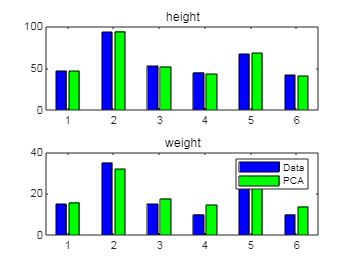

subplot(2,1,1)
b1=bar([A(:,1),E1(:,1)],'b');
b1(2).FaceColor='g';
title('height')
subplot(2,1,2)
b2=bar([A(:,2),E1(:,2)],'b');
b2(2).FaceColor='g';
legend('Data','PCA')
title('weight')

数字图像处理

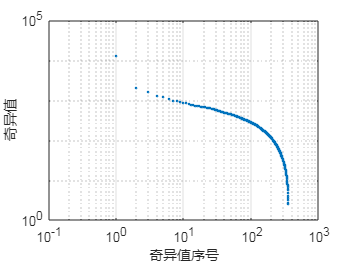

load detail
figure
[U,S,V] = svd(X);
sigma = diag(S); 
set(gcf,'Color','W')
loglog(sigma,'.')
grid on
xlim([10^(-1),10^3])
xlabel('奇异值序号')
ylabel('奇异值')

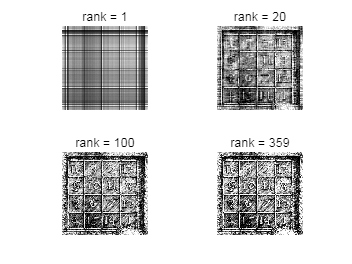

figure
set(gcf,'Color','w')
re=[1,20,100,rank(X)];
for jj=1:4
    if jj<4
        kk=1:re(jj);
        E=U(:,kk)*S(kk,kk)*V(:,kk)';
    else
        E=X;
    end
    subplot(2,2,jj)
    image(E)
    colormap(gray(64))
    axis image, axis off
    title(['rank = ' int2str(re(jj))])
end